# Explores some basic concepts of cell arrays.

a = ['David', 'John', 'Stephen']  % list array[]

a = 'DavidJohnStephen'

b = ['David  '; 'John   '; 'Stephen']

b = 3×7 char array
    'David  '
    'John   '
    'Stephen'


size(b)

ans =      3     7


c = char('David', 'John', 'Stephen') % char array()

c = 3×7 char array
    'David  '
    'John   '
    'Stephen'


size(c)

ans =      3     7


d = {'David', 'John', 'Stephen'}  % cell array{}

d = 1×3 cell array
    {'David'}    {'John'}    {'Stephen'}


d(1)

ans = 1×1 cell array
    {'David'}


d{1}

ans = 'David'

d{1}(1)

ans = 'D'

d{3}(7)

ans = 'n'

# Explores some basic concepts of cell arrays.

a = 45;
b = 'David';
c = [1, 2, 3];
d = [4, 5; 6, 7];
e = {a, b; c, d} 

e = 2×2 cell array
    {[      45]}    {'David'   }
    {1×3 double}    {2×2 double}


disp(e)

    [        45]    'David'     
    [1×3 double]    [2×2 double]



celldisp(e) % disp 每一個cell

 
e{1,1} =
 
    45

 
 
e{2,1} =
 
     1     2     3

 
 
e{1,2} =
 
David
 
 
e{2,2} =
 
     4     5
     6     7

 


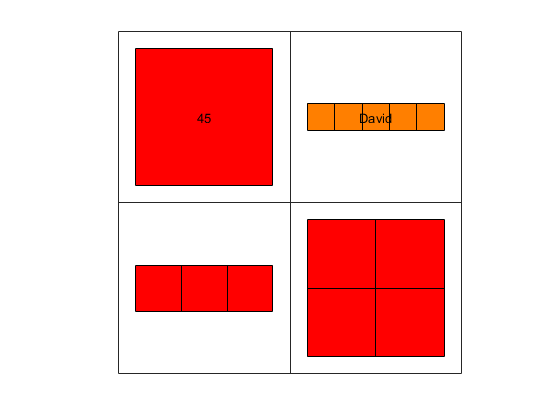

cellplot(e) % Graphically display structure of cell array

e{1,1}

ans = 45

e{2,1}(2)

ans = 2

e{1,2}(1)

ans = 'D'

e{2,2}(2,1)

ans = 6

# Demonstrates a variable-length inputargument function

p = area('circle', 5)

p = 78.5398

q = area('square', 6)

q = 36

s = area('rectangle', 7, 8)

s = 56

t = area('triangle', 'bh', 9, 10)

t = 45

u = area('triangle', 'abc', 5, 6, 7)

u = 14.6969

# Demonstrates a variablelength input-and-outoutargument function.

Ac = properties('circle', 5)

Ac = 78.5398

As = properties('square', 6)

As = 36

Ar = properties('rectangle', 7, 8)

Ar = 56

[Ac, Ic] = properties('circle', 5)

Ac = 78.5398

Ic = 490.8739

[As, Is] = properties('square', 6)

As = 36

Is = 108

[Ar, Ir] = properties('rectangle', 7, 8)

Ar = 56

Ir = 298.6667

# Demonstrates some basic concepts of structures.

node.x = 1;
node.y = 1;
node.supportx = 0;
node.supporty = 0;
node.loadx = 0;
node.loady = -1000;
disp(node)

           x: 1
           y: 1
    supportx: 0
    supporty: 0
       loadx: 0
       loady: -1000



clear
node = struct('x',1,'y',1,'supportx',0,'supporty',0,'loadx',0,'loady',-1000) % 建立結構=> 類似 Python dict

node = struct with fields:
           x: 1
           y: 1
    supportx: 0
    supporty: 0
       loadx: 0
       loady: -1000


Nodes(1) = node

Nodes = struct with fields:
           x: 1
           y: 1
    supportx: 0
    supporty: 0
       loadx: 0
       loady: -1000


Nodes(2) = struct('x',0,'y',0,'supportx',1,'supporty',1,'loadx',0,'loady',0);
Nodes(3) = struct('x',2,'y',0,'supportx',0,'supporty',1,'loadx',0,'loady',0);
disp(Nodes)

  1×3 struct array with fields:

    x
    y
    supportx
    supporty
    loadx
    loady



Nodes(1).x = 5.6;
disp(Nodes(1))

           x: 5.6000
           y: 1
    supportx: 0
    supporty: 0
       loadx: 0
       loady: -1000



disp(node)

           x: 1
           y: 1
    supportx: 0
    supporty: 0
       loadx: 0
       loady: -1000



fieldnames(Nodes)

ans = 6×1 cell array
    {'x'       }
    {'y'       }
    {'supportx'}
    {'supporty'}
    {'loadx'   }
    {'loady'   }


# Modifies Example03_15, using structures to represent nodal/member data.

Nodes = struct; Members = struct;
disp(' 1. Input nodal coordinates')

 1. Input nodal coordinates


disp(' 2. Input connecting nodes of members')

 2. Input connecting nodes of members


disp(' 3. Input three supports')

 3. Input three supports


disp(' 4. Input loads')

 4. Input loads


disp(' 5. Print truss')

 5. Print truss


disp(' 6. Solve truss')

 6. Solve truss


disp(' 7. Print results')

 7. Print results


disp(' 8. Save data')

 8. Save data


disp(' 9. Load data')

 9. Load data


disp('10. Quit')

10. Quit


while 1
    task = input('Enter the task number: ');
    switch task
        case 1
            Nodes = inputNodes(Nodes);
        case 2
            Members = inputMembers(Members);
        case 3
            Nodes = inputSupports(Nodes);
        case 4
            Nodes = inputLoads(Nodes);
        case 5
            printTruss(Nodes, Members)
        case 6
            [Nodes, Members] = solveTruss(Nodes, Members);
        case 7
            printResults(Nodes, Members)
        case 8
            saveAll(Nodes, Members)
        case 9
            [Nodes, Members] = loadAll;
        case 10
            break
    end
end

Statically indeterminate!


Unable to perform assignment because dot indexing is not supported for variables of this type.

Error in Example1>inputSupports (line 285)
    Nodes(i).supportx = 0;

# Demonstrates some basic concepts of tables.

x = [1, 0, 2]'; y = [1, 0, 0]';
supportx = [0, 1, 0]'; supporty = [0, 1, 1]';
loadx = [0, 0, 0]'; loady = [-1000, 0, 0]';
Nodes = table(x, y, supportx, supporty, loadx, loady) % Table array with named variables that can contain different types

Nodes = 3×6 table
    x    y    supportx    supporty    loadx    loady
    _    _    ________    ________    _____    _____

    1    1       0           0          0      -1000
    0    0       1           1          0          0
    2    0       0           1          0          0


Nodes.Properties;
Nodes.Properties.RowNames = {'top', 'left', 'right'};
% disp(Nodes);
size(Nodes); % 3 X 6的table
Nodes = sortrows(Nodes, {'x', 'y'}); % sortrows: 矩陣依某一行或某一列{x,y}排序
node = Nodes(2,:);
Nodes(4,:) = array2table([2, 2, 0, 0, 100, 200]); % array2table 將array轉為table放入Node第4列
Nodes.Properties.RowNames{4} = 'node4'; % 第4列改名為node4
Nodes(5,:) = cell2table({0, 2, 0, 0, 0, 0});
n = struct('x', 1.5, 'y', 0.5, ...
    'supportx', 0, 'supporty', 0, 'loadx', 0, 'loady',0)

n = struct with fields:
           x: 1.5000
           y: 0.5000
    supportx: 0
    supporty: 0
       loadx: 0
       loady: 0


Nodes = [Nodes; struct2table(n)];
Nodes(6,5) = array2table(300)

Nodes = 6×6 table
              x      y     supportx    supporty    loadx    loady
             ___    ___    ________    ________    _____    _____

    left       0      0       1           1           0         0
    top        1      1       0           0           0     -1000
    right      2      0       0           1           0         0
    node4      2      2       0           0         100       200
    Row5       0      2       0           0           0         0
    Row6     1.5    0.5       0           0         300         0


class(Nodes(6,5)) % class : 返回對象的數據類型

ans = 'table'

Nodes.loady(6) = 150;
class(Nodes.loadx(6))

ans = 'double'

disp(Nodes)

              x      y     supportx    supporty    loadx    loady
             ___    ___    ________    ________    _____    _____

    left       0      0       1           1           0         0
    top        1      1       0           0           0     -1000
    right      2      0       0           1           0         0
    node4      2      2       0           0         100       200
    Row5       0      2       0           0           0         0
    Row6     1.5    0.5       0           0         300       150



Nodes(4:6,:) = [];
disp(Nodes)

             x    y    supportx    supporty    loadx    loady
             _    _    ________    ________    _____    _____

    left     0    0       1           1          0          0
    top      1    1       0           0          0      -1000
    right    2    0       0           1          0          0



Nodes(1:3,:) = [];
size(Nodes)

ans =      0     6


# Creates a cell array to store the polymer data and converts the cell array to a structure array and to a table

Polymer_Cell = {'Polyethylene',               'PE',  135,  56, 0.96;
                'Polypropylene',              'PP',  171,  86, 0.95;
                'Polyoxymethylene',           'POM', 180,  90, 1.42;
                'Polyethylene terephthalate', 'PET', 266, 158, 1.38};
PET_Name = Polymer_Cell{4,1}; % accessing from cell index
PET_Melting = Polymer_Cell{4,3};

Field = {'Name', 'Abbreviation', 'Melting', 'Crystallization', 'Density'};
Polymer_Structure = cell2struct(Polymer_Cell, Field, 2);  % cell2struct(a, fields, dim)
PET_Name = Polymer_Structure(4).Name;
PET_Melting = Polymer_Structure(4).Melting;

Polymer_Table = cell2table(Polymer_Cell, 'VariableNames', Field)

Polymer_Table = 4×5 table
                Name                Abbreviation    Melting    Crystallization    Density
    ____________________________    ____________    _______    _______________    _______

    'Polyethylene'                     'PE'           135             56           0.96  
    'Polypropylene'                    'PP'           171             86           0.95  
    'Polyoxymethylene'                 'POM'          180             90           1.42  
    'Polyethylene terephthalate'       'PET'          266            158           1.38  


PET_Name = Polymer_Table.Name(4)

PET_Name = 1×1 cell array
    {'Polyethylene terephthalate'}


PET_Melting = Polymer_Table.Melting(4)

PET_Melting = 266

PET_Name = Polymer_Table(4,1)

PET_Name = table
                Name            
    ____________________________

    'Polyethylene terephthalate'


PET_Melting = Polymer_Table(4,3)

PET_Melting = table
    Melting
    _______

      266  


# Creates a structure array to store the polymer data and converts the structure array to a cell array and to a table.

Polymer_Structure = [struct('Name', 'Polyethylene',                ...
                            'Abbreviation', 'PE',                  ...
                            'Melting', 135,                        ...
                            'Crystallization', 56,                 ...
                            'Density', 0.96);
                     struct('Name', 'Polypropylene',               ...
                            'Abbreviation', 'PP',                  ...
                            'Melting', 171,                        ...
                            'Crystallization', 86,                 ...
                            'Density', 0.95);
                     struct('Name', 'Polyoxymethylene',            ...
                            'Abbreviation', 'POM',                 ...
                            'Melting', 180,                        ...
                            'Crystallization', 90,                 ...
                            'Density', 1.42);
                     struct('Name', 'Polyethylene terephthalate',  ...
                            'Abbreviation', 'PET',                 ...
                            'Melting', 266,                        ...
                            'Crystallization', 158',               ...
                            'Density', 1.38)];
PET_Name = Polymer_Structure(4).Name

PET_Name = 'Polyethylene terephthalate'

PET_Melting = Polymer_Structure(4).Melting

PET_Melting = 266


Polymer_Cell = struct2cell(Polymer_Structure);
Polymer_Cell = Polymer_Cell';
PET_Name = Polymer_Cell{4,1}

PET_Name = 'Polyethylene terephthalate'

PET_Melting = Polymer_Cell{4,3}

PET_Melting = 266


Polymer_Table = struct2table(Polymer_Structure);
PET_Name = Polymer_Table.Name(4)

PET_Name = 1×1 cell array
    {'Polyethylene terephthalate'}


PET_Melting = Polymer_Table.Melting(4)

PET_Melting = 266

PET_Name = Polymer_Table(4,1)

PET_Name = table
                Name            
    ____________________________

    'Polyethylene terephthalate'


PET_Melting = Polymer_Table(4,3)

PET_Melting = table
    Melting
    _______

      266  


# Creates a table to store the polymer data and converts the table to a cell array and to a structure array.

Name = {'Polyethylene', 'Polypropylene', 'Polyoxymethylene', ...
        'Polyethylene terephthalate'}';
Abbreviation = {'PE', 'PP', 'POM', 'PET'}';
Melting = [135, 171, 180, 266]';
Crystallization = [56, 86, 90, 1585]';
Density = [0.96, 0.95, 1.42, 1.38]';
Polymer_Table = table(Name,Abbreviation,Melting,Crystallization,Density);
PET_Name = Polymer_Table.Name(4)

PET_Name = 1×1 cell array
    {'Polyethylene terephthalate'}


PET_Melting = Polymer_Table.Melting(4)

PET_Melting = 266

PET_Name = Polymer_Table(4,1)

PET_Name = table
                Name            
    ____________________________

    'Polyethylene terephthalate'


PET_Melting = Polymer_Table(4,3)

PET_Melting = table
    Melting
    _______

      266  



Polymer_Cell = table2cell(Polymer_Table);
PET_Name = Polymer_Cell{4,1}

PET_Name = 'Polyethylene terephthalate'

PET_Melting = Polymer_Cell{4,3}

PET_Melting = 266


Polymer_Structure = table2struct(Polymer_Table);
PET_Name = Polymer_Structure(4).Name

PET_Name = 'Polyethylene terephthalate'

PET_Melting = Polymer_Structure(4).Melting

PET_Melting = 266

# Demonstrates the use of a user-defined class poly.

a = Poly(3,2,1) % 將根轉為多項式.

a = +3.000000x^2+2.000000x+1.000000

b = Poly(5,6)

b = +5.000000x+6.000000

c = Poly(8)

c = +8.000000

d = a+b

d = +3.000000x^2+7.000000x+7.000000

e = -a-b*(-c+a)

e = -15.000000x^3-31.000000x^2+21.000000x+41.000000

value(e, 2.5)

ans = -334.6250

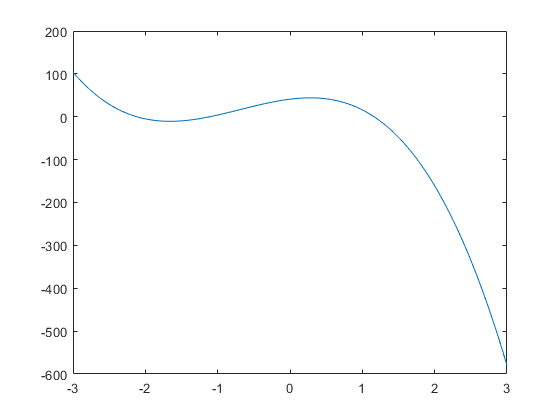

x = linspace(-3,3);
y = value(e,x);
plot(x,y)

# function

function output = area(varargin)
output = 0;
switch varargin{1}
    case 'circle'
        if nargin == 2          % nargin : 輸入參數之個數
            r = varargin{2};
            output = pi*r^2;
        end       
    case 'square'
        if nargin == 2
            a = varargin{2};
            output = a^2;
        end
    case 'rectangle'
        if nargin == 3
            b = varargin{2};
            h = varargin{3};
            output = b*h;
        end
    case 'triangle'
        if strcmp(varargin{2},'bh') && nargin == 4
            b = varargin{3};
            h = varargin{4};
            output = b*h/2;
        elseif strcmp(varargin{2}, 'abc') && nargin == 5
            a = varargin{3};
            b = varargin{4};
            c = varargin{5};
            R = a*b*c/sqrt((a+b+c)*(a-b+c)*(b-c+a)*(c-a+b));
            output = a*b*c/(4*R);
        end
end
end
% -------------------------------------------------------------------
function varargout = properties(varargin)
varargout{1} = 0;
switch varargin{1}
    case 'circle'
        if nargin == 2
            r = varargin{2};
            varargout{1} = pi*r^2;
            if nargout == 2
                varargout{2} = pi*r^4/4;
            end
        end
    case 'square'
        if nargin == 2
            a = varargin{2};
            varargout{1} = a^2;
            if nargout == 2
                varargout{2} = a^4/12;
            end
        end
    case 'rectangle'
        if nargin == 3
            b = varargin{2};
            h = varargin{3};
            varargout{1} = b*h;
            if nargout == 2
                varargout{2} = b*h^3/12;
            end
        end
end
end
% -------------------------------------------------------------------
function output = inputNodes(Nodes)
while 1
    data = input('Enter [node, x, y] or 0 to stop: ');
    if data(1) == 0
        break
    else
        Nodes(data(1)).x = data(2);
        Nodes(data(1)).y = data(3);
    end
end
output = Nodes;
end

function output = inputMembers(Members)
m = 0;
while 1
    data = input('Enter [node1, node2] or 0 to stop: ');
    if data(1) == 0
        break
    else
        m = m+1;
        Members(m).node1 = data(1);
        Members(m).node2 = data(2);
    end
end
output = Members;
end

function output = inputSupports(Nodes)
for i = 1:size(Nodes,2)
    Nodes(i).supportx = 0;
    Nodes(i).supporty = 0;
end
for k = 1:3
    data = input('Enter [node, dir] (dir: ''x'' or ''y''): ');
    if data(2) == 'x'
        Nodes(data(1)).supportx = 1;
    elseif data(2) == 'y'
        Nodes(data(1)).supporty = 1;
    end
end
output = Nodes;
end

function output = inputLoads(Nodes)
for i = 1:size(Nodes,2)
    Nodes(i).loadx = 0;
    Nodes(i).loady = 0;
end
while 1
    data = input('Enter [node, load-x, load-y] or 0 to stop: ');
    if data(1) == 0
        break
    else
        Nodes(data(1)).loadx = data(2);
        Nodes(data(1)).loady = data(3);
    end
end
output = Nodes;
end

function printTruss(Nodes, Members)
if (size(fieldnames(Nodes),1)<6 || size(fieldnames(Members),1)<2)
    disp('Truss data not complete'); return
end
fprintf('\nNodal Data\n')
fprintf('Node        x        y  Support-x  Support-y   Load-x   Load-y\n')
for k = 1:size(Nodes,2)
    fprintf('%4.0f%9.2f%9.2f%11.0f%11.0f%9.0f%9.0f\n', ...
        k, Nodes(k).x, Nodes(k).y, ...
        Nodes(k).supportx, Nodes(k).supporty, ...
        Nodes(k).loadx, Nodes(k).loady)
end
fprintf('\nMember Data\n')
fprintf('Member  Node1    Node2\n')
for k = 1:size(Members,2)
    fprintf('%4.0f%9.0f%9.0f\n', k, Members(k).node1, Members(k).node2)
end
end

function printResults(Nodes, Members)
if (size(fieldnames(Nodes),1)<8 || size(fieldnames(Members),1)<3)
    disp('Results not available!'), return
end
fprintf('\nReaction Forces\n')
fprintf('Node  Reaction-x  Reaction-y\n')
for k = 1:size(Nodes,2)
    fprintf('%4.0f%12.2f%12.2f\n', k, Nodes(k).reactionx, Nodes(k).reactiony)
end
fprintf('\nMember Forces\n')
fprintf('Member     Force\n')
for k = 1:size(Members,2)
    fprintf('%4.0f%12.2f\n', k, Members(k).force)
end
end

function saveAll(Nodes, Members)
fileName = input('Enter file name (default Datafile): ', 's');
if isempty(fileName)
    fileName = 'Datafile';
end
save(fileName, 'Nodes', 'Members')
end

function [Nodes, Members] = loadAll
fileName = input('Enter file name (default Datafile): ', 's');
if isempty(fileName)
    fileName = 'Datafile';
end
load(fileName)
end

function [outNodes, outMembers] = solveTruss(Nodes, Members)
n = size(Nodes,2); m = size(Members,2);
if (m+3) < 2*n
    disp('Unstable!')
    outNodes = 0; outMembers = 0; return
elseif (m+3) > 2*n
    disp('Statically indeterminate!')
    outNodes = 0; outMembers = 0; return
end
A = zeros(2*n, 2*n); loads = zeros(2*n,1); nsupport = 0;
for i = 1:n
    for j = 1:m
        if Members(j).node1 == i || Members(j).node2 == i
            if Members(j).node1 == i
                n1 = i; n2 = Members(j).node2;
            elseif Members(j).node2 == i
                n1 = i; n2 = Members(j).node1;
            end
            x1 = Nodes(n1).x; y1 = Nodes(n1).y;
            x2 = Nodes(n2).x; y2 = Nodes(n2).y;
            L = sqrt((x2-x1)^2+(y2-y1)^2);
            A(2*i-1,j) = (x2-x1)/L;
            A(2*i,  j) = (y2-y1)/L;
        end
    end
    if (Nodes(i).supportx == 1)
        nsupport = nsupport+1;
        A(2*i-1,m+nsupport) = 1;
    end
    if (Nodes(i).supporty == 1)
        nsupport = nsupport+1;
        A(2*i, m+nsupport) = 1;
    end
    loads(2*i-1) = -Nodes(i).loadx;
    loads(2*i)   = -Nodes(i).loady;
end
forces = A\loads;
for j = 1:m
    Members(j).force = forces(j);
end
nsupport = 0;
for i = 1:n
    Nodes(i).reactionx = 0;
    Nodes(i).reactiony = 0;
    if (Nodes(i).supportx == 1)
        nsupport = nsupport+1;
        Nodes(i).reactionx = forces(m+nsupport);
    end
    if (Nodes(i).supporty == 1)
        nsupport = nsupport+1;
        Nodes(i).reactiony = forces(m+nsupport);
    end
end
outNodes = Nodes; outMembers = Members;
disp('Solved successfully.')
end

% -------------------------------------------------------------------